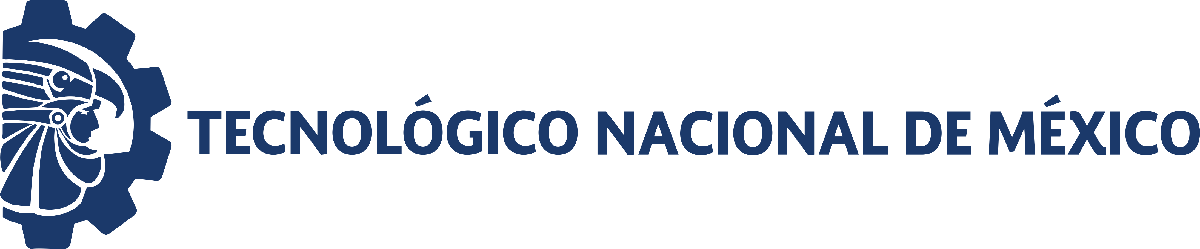                                 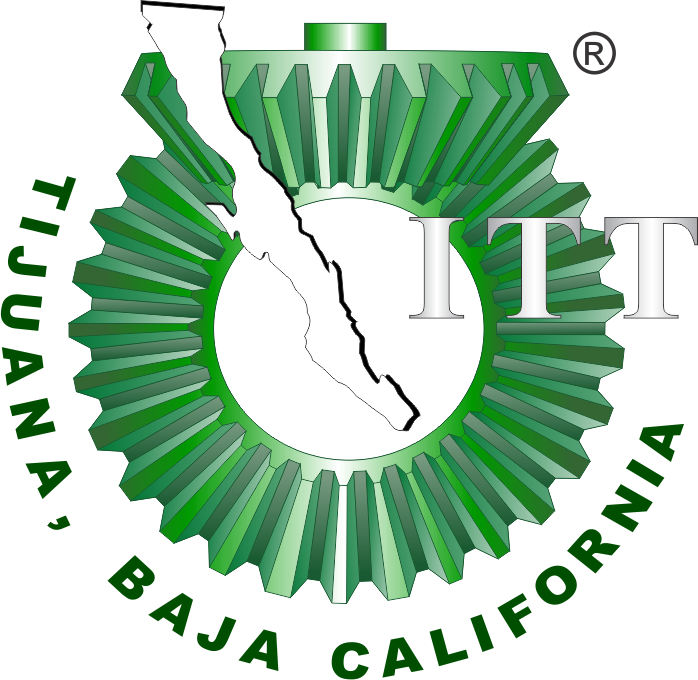

# Práctica 3: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

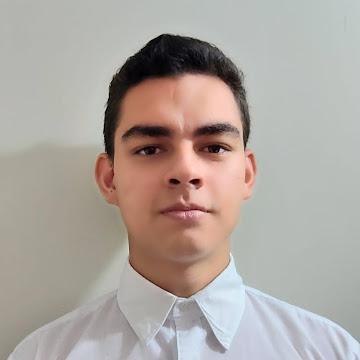

Nombre del alumno: **Aron Cervantes Armenta**

Número de control: **22211750**

Correo institucional: **l22211750@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

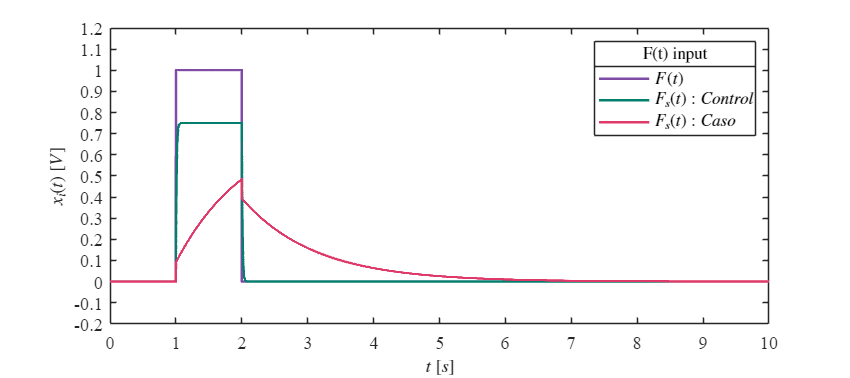

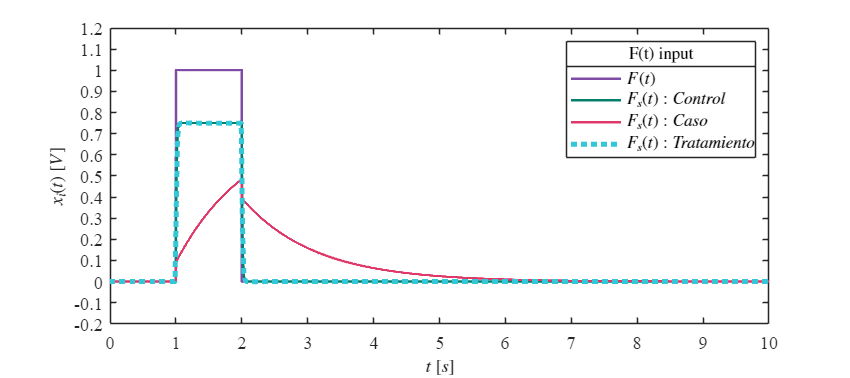

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23tb';
parameters.MaxStep = '1E-3';
set_param('Sistema/F(t)','Amplitude','1');

Signal = 'F(t)';
x = sim(file,parameters);
%writematrix(x.F,'signal.xlsx')
plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,Signal)

## Funcion: Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Fs3,Signal)

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors);

    plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L = legend('$F(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Box','On');
    title(L,[Signal,' input'],'FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    if Signal == "F(t)"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')


    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors);

    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4),'LineWidth',3);
    L = legend('$F(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$','$F_{s}(t): Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Box','On');
    title(L,[Signal,' input'],'FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    if Signal == "F(t)"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);
    end

    exportgraphics(gcf,[Signal,'_PID.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'_PID.png'],'ContentType','Vector')

end